# Laboratorio 1 de señales

Se tomaron los respectivos datos usando una stm32 y su sensor análogo, con una función senosoidal configurada en el generador del laboratorio como se especifica en la guía.

Se tomaron muestras a una frecuencia de doscientas por segundo

Por lo que cada muestra tiene un espacio de 5ms.

Para el ejercicio propuesto se van a trabajar todos los vectores con 200 muestras

El objetivo es ver los errores de cuantificación para observar cómo afecta la resolución del sensor en la toma de muestras

archivos=["datos10hz.txt","datos20hz.txt","datos30hz.txt","datos40hz.txt",...
    "datos50hz.txt","datos60hz.txt","datos70hz.txt", ...
    "datos80hz.txt","datos90hz.txt","datos100hz.txt"];

frecuenciaMuestreo      =200;%[Hz]
frecuenciaSenal         =30;%[Hz]
tiempoGrafica           =0.5;%[s]


Seleccione el archivo de muestras a graficar:

archivoAnalizado=archivos(3);

                  

%recuperar los datos del archivo
[datosAdc,~]=importdata(archivoAnalizado);
datosAdc=datosAdc'

datosAdc =     2.7012    3.3000    2.5675    0.7704         0    0.5021    1.9316    3.2154    3.0905    2.0147    0.4618    0.0806    0.9074    2.1976    3.2645    2.9454    1.5263    0.1499    0.2369    1.2853    2.7117    3.3000    2.5127    0.9348    0.0782    0.5867    1.8035    3.0550    3.2259    1.9832    0.4674    0.1177    0.8985    2.2395    3.2105    2.9680    1.2152    0.2700    0.2917    1.1588    2.7021    3.3000    2.4031    0.8913    0.1048    0.5166    1.7536    3.2428    3.2452    1.9429


numeroMuestras = tiempoGrafica*frecuenciaMuestreo;

%creamos un vector de tiempo para el eje x
t=0:1/frecuenciaMuestreo:tiempoGrafica; %[s]

%recortar los datos
datosAdc=datosAdc(250:250+numeroMuestras);


%calculamos frecuencia angular
frecuenciaAngular=double(2*pi()*frecuenciaSenal);

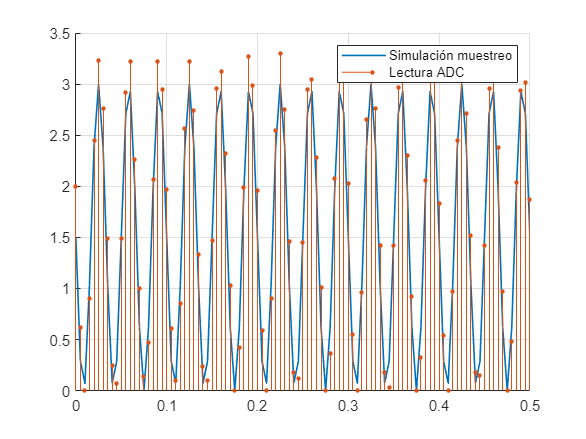

fase = 3.1416;

%se hace la simulación de muestreo
datosSim=1.5*sin(frecuenciaAngular.*t+fase)+1.5;

figure
grid on
hold on
plot(t,datosSim,LineWidth=1.1)
stem(t,datosAdc, LineWidth=0.05,MarkerSize=9,Marker=".")
legend('Simulación muestreo','Lectura ADC')


valor_psnr=psnr(datosAdc,datosSim)

valor_psnr = 11.5607

Error_cuadratico_edio=immse(datosAdc,datosSim)

Error_cuadratico_edio = 0.0698


%calcul de la media
media_teorica=mean(datosSim)

media_teorica = 1.5000

media_experimental=mean(datosAdc)

media_experimental = 1.6654

Error_de_estimacion=(abs(media_teorica-media_experimental))/media_teorica

Error_de_estimacion = 0.1102


%calculo de la varianza
varianzaE=var(datosAdc)

varianzaE = 1.3496

varianzaT=var(datosSim)

varianzaT = 1.1250

ErrorDeLasVarianzas=(abs(varianzaT-varianzaE))/varianzaT

ErrorDeLasVarianzas = 0.1996